% конструктор + метод display
q = polynom()

 
q = 
 
     0
 


q1 = polynom([0 0 1]) % исправлен метод : начальные нули не входят в вектор коэффициентов полинома

 
q1 = 
 
     1
 


q2 = polynom([0 0 0]) % исправлен метод : создание объекта с переданным вектором из нулей эквивалентно созданию объекта без переданных аргументов 

 
q2 = 
 
     0
 


 
p1 = 
 
     x^3 - 2*x^2 - 5
 


p = polynom([1 0 -2 -5])

 
p = 
 
     x^3 - 2*x - 5
 


r = polynom(p)

 
r = 
 
     x^3 - 2*x - 5
 


t = polynom([1:5])

 
t = 
 
     x^4 + 2*x^3 + 3*x^2 + 4*x + 5
 


% конвертер в double
double(q)


ans =

     []



double(q1)

ans = 1

double(q2)


ans =

     []




double(p)

ans =      1     0    -2    -5


double(t)

ans =      1     2     3     4     5


% конвертер в char
char(p)

ans = 'x^3 - 2*x - 5'

char(t)

ans = 'x^4 + 2*x^3 + 3*x^2 + 4*x + 5'

char(q)

ans = '0'


x = 3;
eval(char(p))

ans = 16

x = -2;
eval(char(polynom([1 0 0])))

ans = 4

% subsref
t

 
t = 
 
     x^4 + 2*x^3 + 3*x^2 + 4*x + 5
 


t(1)

ans = 15

m = polynom([1 0 0])

 
m = 
 
     x^2
 


m([2, -2])

ans =      4     4


% плюс
m+t

 
ans = 
 
     x^4 + 2*x^3 + 4*x^2 + 4*x + 5
 


m+1

 
ans = 
 
     x^2 + 1
 


q+1

 
ans = 
 
     1
 


% минус
m - 1

 
ans = 
 
     x^2 - 1
 


t - m

 
ans = 
 
     x^4 + 2*x^3 + 2*x^2 + 4*x + 5
 


% умножение
m*0

 
ans = 
 
     0
 


m*q % исправлено, в коде был недочет: на нулевой полином нельзя было умножить (ругалась функция conv)

 
ans = 
 
     0
 



m*p

 
ans = 
 
     x^5 - 2*x^3 - 5*x^2
 


% корни многочлена
m

 
m = 
 
     x^2
 


roots(m) % исправлен метод: раньше возвращались два одинаковых корня

ans = 0

roots(q) % исправлен метод: раньше возвращалось сообщение 0×1 empty double column vector


ans =

     []




roots(p)

ans =   -1.0473 - 1.1359i
  -1.0473 + 1.1359i
   2.0946 + 0.0000i


% значение многочлена в точке(точках)
polyval(p, 1)

ans = -6

polyval(m, [0, 1, -3])

ans =      0     1     9


polyval(q, 1)

ans = 0

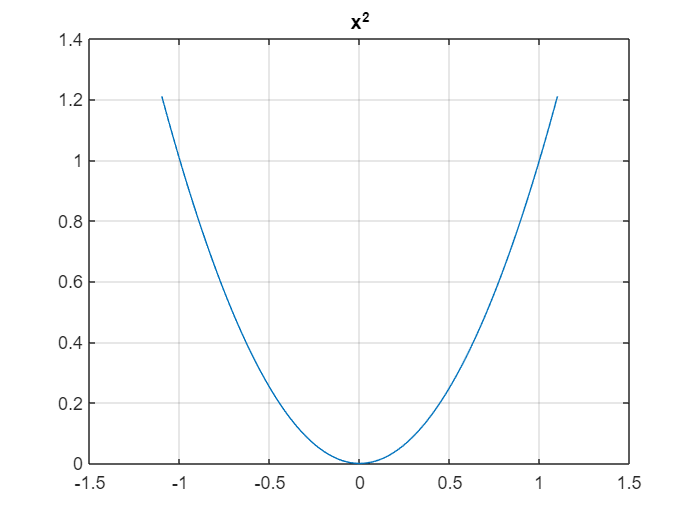

% plot
plot(m) % исправлен метод: раньше не рисовался график функции с наибольшим корнем 0

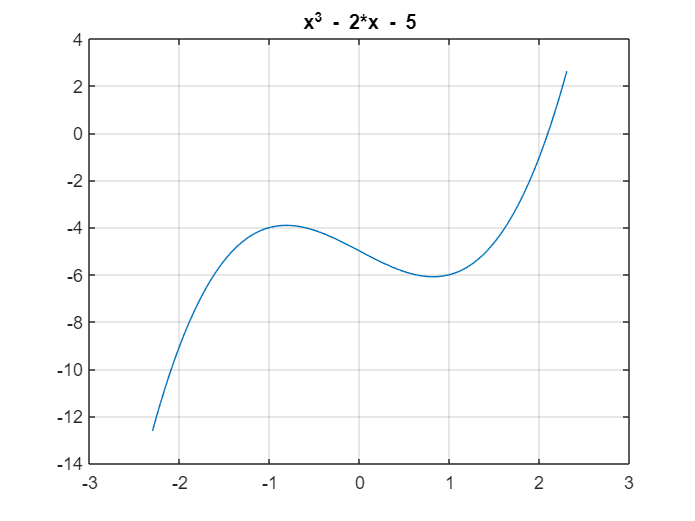

plot(p)

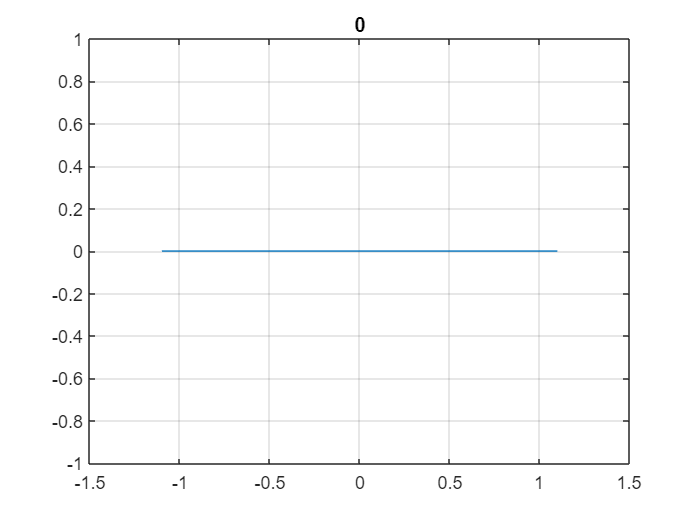

plot(q) % исправлен метод: раньше была ошибка, т.к. max(abs(roots([]))) это 0×1 empty double column vector, то нельзя было осуществить матричное умножение

% производная
diff(m)

 
ans = 
 
     2*x
 


diff(q)

 
ans = 
 
     0
 


p

 
p = 
 
     x^3 - 2*x - 5
 


diff(p)

 
ans = 
 
     3*x^2 - 2
 


% интеграл
int(m)

 
ans = 
 
     0.33333*x^3
 


int(m, 5)

 
ans = 
 
     0.33333*x^3 + 5
 
